展示不同群体随时相变化占比图

## 语法

## 示例

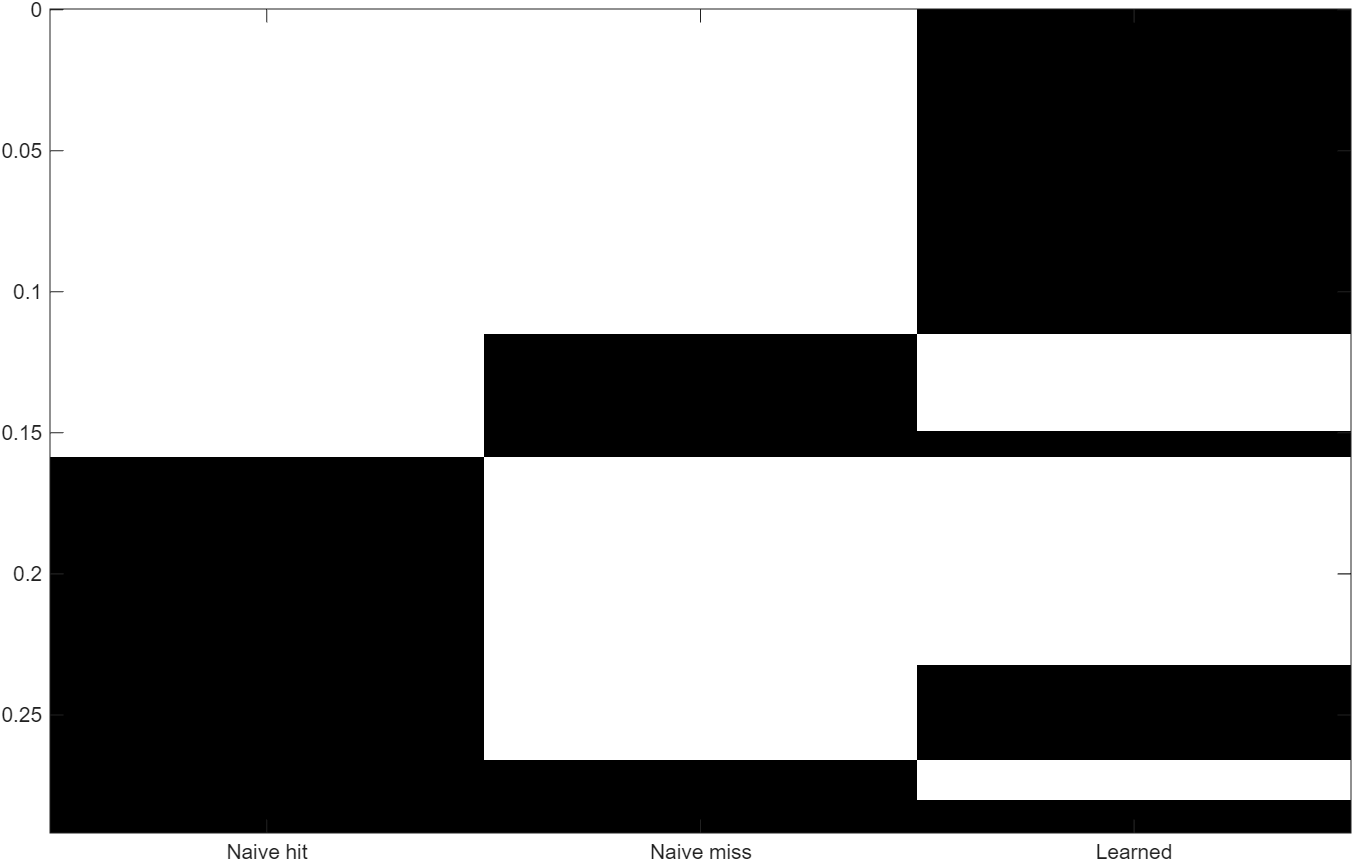

## 输入参数

LogicalTable table，包含各细胞是否活跃于各时相的逻辑表，一行一个细胞，一列一个时相，各列都是(:,1)logical。将用内置imagesc绘制表中所有不全为false的细胞，黑色表示活跃，白色表示不活跃。横轴时相，纵轴占比

function EnsemblePhaseGraph(LogicalTable)
LogicalTable=sortrows(LogicalTable);
AnyTrue=any(LogicalTable{:,:},2);
NumPhases=width(LogicalTable);
imagesc([1,NumPhases],[0,mean(AnyTrue)],LogicalTable{AnyTrue,:});
xticks(1:NumPhases);
xticklabels(LogicalTable.Properties.VariableNames);
colormap([1,1,1;0,0,0]);
end